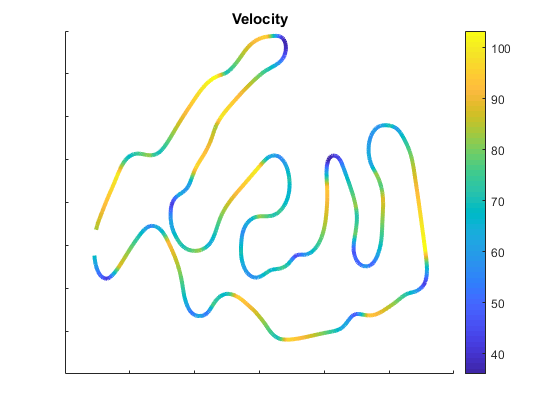


interpVel = interp1(resultData.distance, resultData.velocity, distance);
x = course(:,1)';
y = course(:,2)';
z = interpVel'.*3.6;
C = interpVel'.*3.6;

surface([x;x],[y;y],[z;z],[C;C],...
    'FaceColor','none',...
    'EdgeColor','interp', 'LineWidth', 3);
title('Velocity')
colorbar
set(gca,'XTickLabel',[],'YTickLabel',[]);

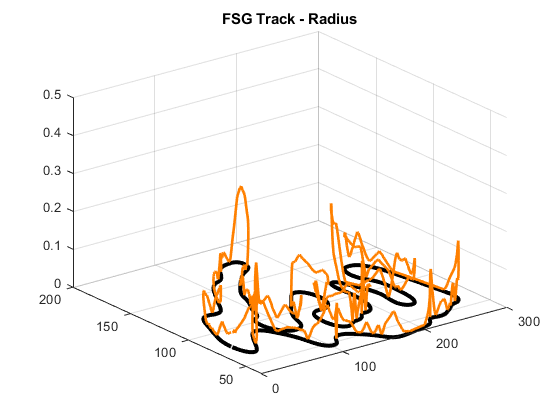




figure('Name', 'FSG Track - Radius')
plot3(course(:,1),course(:,2),1./(course(:,3)),'Color', [1 0.5 0], "LineWidth", 2)
zlim ([0 0.5])
hold on
plot3(course(:,1),course(:,2),course(:,3).*0,'k','LineWidth',3)
% plot3(apexData.xy(:,1), apexData.xy(:,2), 1:1:length(apexData.locs), 'b o', 'LineWidth', 3)
grid
title('FSG Track - Radius')
hold off

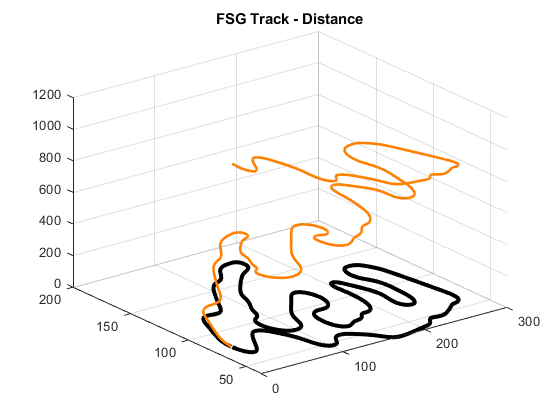


figure('Name', 'FSG Track - Distance')
plot3(course(:,1),course(:,2),distance,'Color', [1 0.5 0], "LineWidth", 2)

% zlim ([0 0.5])
hold on
plot3(course(:,1),course(:,2),course(:,3).*0,'k','LineWidth',3)
% plot3(apexData.xy(:,1), apexData.xy(:,2), 1:1:length(apexData.locs), 'b o', 'LineWidth', 3)
grid
title('FSG Track - Distance')
hold off

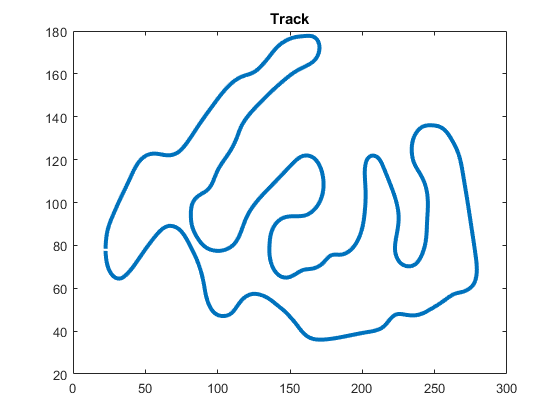


figure()
plot(course(:,1),course(:,2), 'LineWidth', 3)
title ('Track')